https://www.mathworks.com/help/symbolic/solve-a-single-differential-equation.html#mw_70f735e2-7aa7-43a2-97e8-a1ef36640a04

Variables

75,1,1 -> sin wave //ocilates

75,-1,1 -> -ve exponential // toward equilibrium 

75,1,-1 -> +ve exponential 

75,-x,x -> as x increases, fplot(Sol) tends to straight line y = -x+3ish

75,x,-x -> as x increases, fplot(Sol) tends to straight line y = x+3ish

R = 75

R = 75

L = -7

L = -7

C = 7

C = 7

ZIR Equation

syms V(t)
DV = diff(V) 

$$DV(t) = \frac{\partial }{\partial t}V\left(t\right)$$

ode = diff(V,t,2) + (1/(R*C))*diff(V,t) + (1/(L*C))*V

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}V\left(t\right)+\frac{\frac{\partial }{\partial t}V\left(t\right)}{525}-\frac{V\left(t\right)}{49}$$

Initial conditions

condition1 = V(0) == 3

$$condition1 = V\left(0\right)=3$$

condition2 = DV(0) == -(77/(25*C))

$$condition2 = \left({\left(\frac{\partial }{\partial t}V\left(t\right)\right)|}_{t=0}\right)=-\frac{11}{25}$$


conds = [condition1,condition2]

$$conds = \left(\begin{array}{cc} V\left(0\right)=3 & \left({\left(\frac{\partial }{\partial t}V\left(t\right)\right)|}_{t=0}\right)=-\frac{11}{25} \end{array}\right)$$


Sol(t) = dsolve(ode,conds)

$$Sol(t) = {\mathrm{e}}^{-t\,\left(\frac{\sqrt{22501}}{1050}+\frac{1}{1050}\right)}\,\left(\frac{459\,\sqrt{22501}}{45002}+\frac{3}{2}\right)+\frac{3\,\sqrt{22501}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{22501}}{1050}-\frac{1}{1050}\right)}\,\left(\sqrt{22501}-153\right)}{45002}$$

Sol = simplify(Sol)

$$Sol(t) = {\mathrm{e}}^{-t\,\left(\frac{\sqrt{22501}}{1050}+\frac{1}{1050}\right)}\,\left(\frac{459\,\sqrt{22501}}{45002}+\frac{3}{2}\right)+\frac{3\,\sqrt{22501}\,{\mathrm{e}}^{t\,\left(\frac{\sqrt{22501}}{1050}-\frac{1}{1050}\right)}\,\left(\sqrt{22501}-153\right)}{45002}$$

Plotting

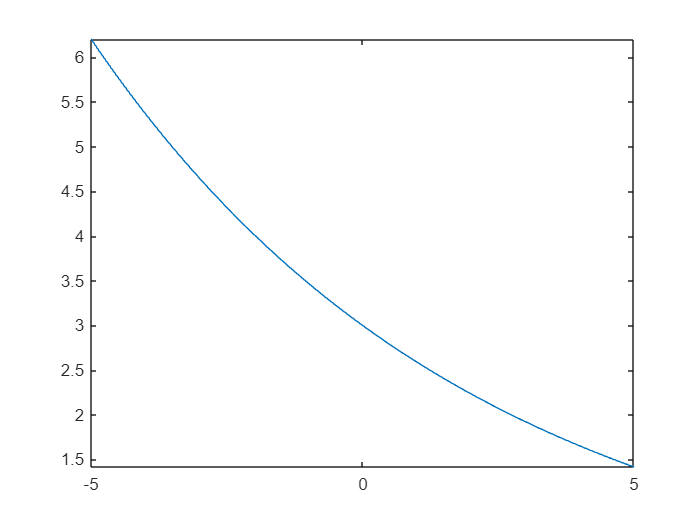

fplot(Sol)